**Initialization**

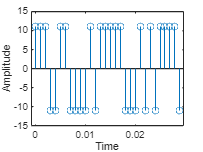

close all ; clear all ; clc

% TUID = 916045319

A = 9 + 2;          % Amplitude
f = (1+3)*1000;     % Frequency KHz

rb = 1000;          % bit rate
Tb = 1/rb;          % bit interval     

fs = 100*rb;        % Sampling rate
Ts = 1/fs;          % Sampling Interval

M = 2;              % Numbe of symbols
N = 30;             % Number of bits to be transmitted

Ns = floor(Tb/Ts);  % Number of samples per bit

% Polar Non return to zero scheme
[t1,pnrz,t2,signal_prnz] = polar_nrz(A,rb,fs,N); 

figure(1)
stem(t1,pnrz);
xlabel('Time')
ylabel('Amplitude')

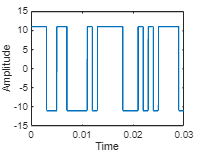


figure(2)
plot(t2,signal_prnz)
xlabel('Time')
ylabel('Amplitude')

**Part 1**

hange the SNR value for 20 dB to −50 dB with an interval of 2 dB to calculate the error rate. Plot the error rate against SNR. Analyze whether the error rate increases or decreases as the SNR changes, and explain your findings.

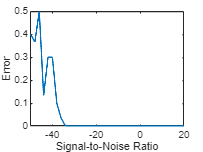

snr_range = 20:-2:-50;
error_range = zeros(size(snr_range));

for i=1:length(snr_range)
    
    % signal to noise power in db
    snr_db = snr_range(i);
    
    % Passing the signal through a noisy channel
    received = awgn(signal_prnz, snr_db);
    
    %% Matched filtering 
    filtered_signal = zeros(1,N);
    
    pulse = ones(1,Ns); % Reference pulse
    
    % Performing matched filtering
    for j = 1:length(signal_prnz)/Ns
        idx = (j-1)*Ns+1:(j-1)*Ns+Ns;
        filtered = conv(received(idx),pulse);
        filtered_signal(j) =  filtered(Ns);
    end
    filtered_signal = filtered_signal/(A^2*Ns);
    
    %% Detection 
    detected = filtered_signal;
    detected(filtered_signal>=0)=1;
    detected(filtered_signal<0)=-1;
    
    %% Performance 
    error = sum(detected~=pnrz/A)/N;

    error_range(i) = error;
end

figure(3)
plot(snr_range, error_range)
ylabel('Error')
xlabel('Signal-to-Noise Ratio')
xlim([min(snr_range), max(snr_range)])

**Part 2**

Consider a transmitted signal encoded with waveforms based on your TUID(7). Plot the transmitted, received and filtered signal for 0 dB SNR. 

Unipolar RZ

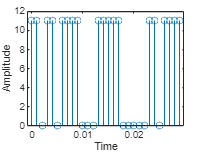

% unipolar Non return to zero scheme
[t1,upnrz,t2,signal_upnrz] = SHANEM_unipolar_nrz(A,rb,fs,N); 

figure(4)
stem(t1,upnrz);
xlabel('Time')
ylabel('Amplitude')

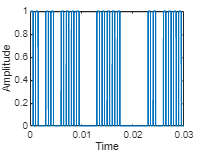


figure(5)
plot(t2,signal_upnrz)
xlabel('Time')
ylabel('Amplitude')

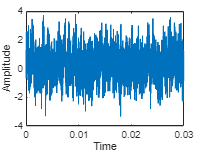


% signal to noise power in db
snr_db = 0;

% Passing the signal through a noisy channel
received = awgn(signal_upnrz, snr_db);

%% Matched filtering 
filtered_signal = zeros(1,N);

pulse = ones(1,Ns); % Reference pulse

% Performing matched filtering
for j = 1:length(signal_upnrz)/Ns
    idx = (j-1)*Ns+1:(j-1)*Ns+Ns;
    filtered = conv(received(idx),pulse);
    filtered_signal(j) = filtered(Ns);
end
filtered_signal = filtered_signal/(A^2*Ns);

%% Detection 
detected = filtered_signal;
detected(filtered_signal>=0)=1;
detected(filtered_signal<0)=-1;

%% Performance 
error = sum(detected~=upnrz/A)/N;

figure(6)
plot(t2,received)
xlabel('Time')
ylabel('Amplitude')

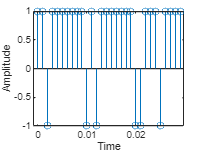


figure(7)
stem(t1,detected);
xlabel('Time')
ylabel('Amplitude')

**Part 3**

Repeat Task 1 using the following waveforms based on your TUID(7). Plot the figures from Task 1 and Task 3 on the same graph for comparison. Discuss your findings.

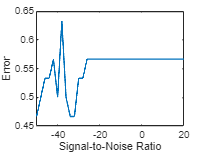

snr_range = 20:-2:-50;
error_range = zeros(size(snr_range));

% Unipolar Non return to zero scheme
[t1,upnrz,t2,signal_upnrz] = unipolar_nrz(A,rb,fs,N); 

for i=1:length(snr_range)
    
    % signal to noise power in db
    snr_db = snr_range(i);
    
    % Passing the signal through a noisy channel
    received = awgn(signal_upnrz, snr_db);
    
    %% Matched filtering 
    filtered_signal = zeros(1,N);
    
    pulse = ones(1,Ns); % Reference pulse
    pulse = pulse.*(A);
    
    % Performing matched filtering
    for j = 1:length(signal_upnrz)/Ns
        idx = (j-1)*Ns+1:(j-1)*Ns+Ns;
        filtered = conv(received(idx),pulse);
        filtered_signal(j) =  filtered(Ns);
    end
    filtered_signal = filtered_signal/(A^2*Ns);
    
    %% Detection 
    detected = filtered_signal;
    detected(filtered_signal>=0.5)=1;
    detected(filtered_signal<0.5)=-1;
    
    %% Performance 
    error = sum(detected~=pnrz/A)/N;

    error_range(i) = error;
end

figure(3)
plot(snr_range, error_range)
ylabel('Error')
xlabel('Signal-to-Noise Ratio')
xlim([min(snr_range), max(snr_range)])